# **PreWork:**   matrix manipulation using tables

## Context:

The `table` data type allows you to use intuative array indexing syntax which is super convenient for matrix manipulations such as those encountered in finite element applications in structural analysis.

## Learning objectives:

In this short tutorial we're going to look at 3 things:

- How to insert data into a table using intuitive indexing labels

- How to access (or use) the data in a table for subsequent matrix calculations

- How to create a sub table from an existing table

`Bradley Horton : 09-Nov-2017, bradley.horton@mathworks.com.au`

## **Part_01:  inserting data into a table:**

Study the following code snippet that uses tables:

Define a "standard" *2x2* matrix containing some data:

my_data     = [ 11, 12;
                21, 22; ]

my_data =     11    12
    21    22


Now create a table filled with ZEROS - NOTE: the column and row labels.               

my_table    =    array2table(  zeros(5,5), ...
                               'VariableNames', {'apple','cat', 'dog', 'jill', 'dan'}, ...
                               'RowNames',      {'apple','cat', 'dog', 'jill', 'dan'} )      

my_table = 5×5 table
             apple    cat    dog    jill    dan
             _____    ___    ___    ____    ___

    apple      0       0      0      0       0 
    cat        0       0      0      0       0 
    dog        0       0      0      0       0 
    jill       0       0      0      0       0 
    dan        0       0      0      0       0 


So let's say that we want to insert `my_data` into `my_table``,` and  specifically we want to insert the data  into particular ROWS and COLUMNS of the table as shown below:

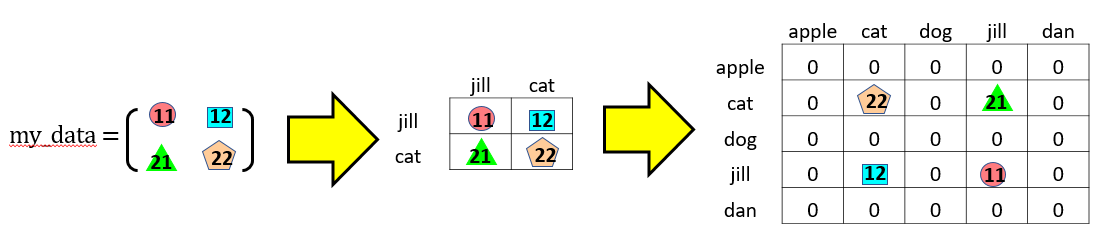

So to accomplish the data insertion as shown above, the following code snippet is how it's done using tables:

              ind_rows  =  {'jill', 'cat'};
              ind_cols  = {'dog', 'dan'}

ind_cols = 1×2 cell array
    {'dog'}    {'dan'}


my_table{ind_rows, ind_cols} = my_data    

my_table = 5×5 table
             apple    cat    dog    jill    dan
             _____    ___    ___    ____    ___

    apple      0       0      0      0       0 
    cat        0       0     21      0      22 
    dog        0       0      0      0       0 
    jill       0       0     11      0      12 
    dan        0       0      0      0       0 


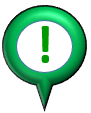And of course assiging scalar values follows the same pattern, ie:

my_table{"dog", "dan"} = 892

my_table = 5×5 table
             apple    cat    dog    jill    dan
             _____    ___    ___    ____    ___

    apple      0       0      0      0        0
    cat        0       0     21      0       22
    dog        0       0      0      0      892
    jill       0       0     11      0       12
    dan        0       0      0      0        0


## **Part_02:  accessing the data in a table for matrix calculations**

Here's how to extract the data in ROW "dog" and COLUMN "dan"

some_value = my_table{"dog", 'dan'}

Here's how to extract all of the data from the `"jill"` COLUMN of our table:

some_column = my_table{:, 'jill'}

Here's how to extract all of the data from the `"cat"` ROW of our table:

some_row = my_table{'cat', : }

Here's how to extract ALL of the data inside the table:

some_matrix = my_table{:, : }

## **Part_03: create a SUB table from an existing table**

Here's how to create a sub table:

some_new_table = my_table(:, [5, 1])

Or, again using the intuitive text labels:

some_new_table = my_table(:, {'dan','apple'})